# Modelado dinámico en Biología Sintética

Yadira Boada

05/03/2022

## Modelado de la expresion genética

### Ecuaciones diferenciales con Matlab

Recordemos comando ode45. Su estructura es la siguiente.

%[t,X] = ode45(@(t,x) modelo(t,x,params),tspan,x0,options);

donde:

`t `es la variable independiente

`x `es la variable (o vector de variables) dependientes 

`modelo` es el nombre de la función que da la ecuación diferencial,

`params` contiene valores de parámetros

`tspan` indica el tiempo durante el cual se quiere obtener la solución,

`x0` representa las condiciones iniciales,

`options` las opciones del algoritmo integrador.

### Expresión Regulada por Factor de Transcripción

Ir al final de este documeto para ver la definición de la funcion.

**Programa principal**

%  Constitutive Gene expression
%   Parameters: structure contains all rates and constants
%   Updated 05/03/2022 by YB, AV

    p.CN = 17;        % plasmid number  pACYC184 (17 copies/cell)  
    p.d1 = log(2)/3;  % mRNA degradation rate  [1/min]
    p.d2 = 0.02;      % degradation rate [1/min]
    p.k2 = 8.23;      % translation rate  [1/min] 
    p.k1 = 1.19;      % transcription rate [1/min] 
    
    p.kon = 0.5;       % Binding rate  [1/min] 
    p.koff = 1;    % Unbinding rate [1/min] 

tfin = 60*3;   %simulation final time [min]
step = 0.01;    %simulation step
tspan = 0:step:tfin-step; 

% options for ode function
opti = odeset('AbsTol',1e-8,'RelTol',1e-6);      
Init = [p.CN 25 0 0 0];  %initial conditions

[t0,x0] = ode23t(@(t,x) model_TF(t,x,p),tspan, Init, opti);
x0

x0 = 1.0e+04 *

    0.0017    0.0025         0         0         0
    0.0015    0.0023    0.0002    0.0000    0.0000
    0.0014    0.0022    0.0003    0.0000    0.0000
    0.0012    0.0020    0.0005    0.0000    0.0000
    0.0011    0.0019    0.0006    0.0000    0.0000
    0.0010    0.0018    0.0007    0.0000    0.0000
    0.0009    0.0017    0.0008    0.0000    0.0000
    0.0009    0.0017    0.0008    0.0000    0.0000
    0.0008    0.0016    0.0009    0.0001    0.0000
    0.0008    0.0016    0.0009    0.0001    0.0000


time = t0/60; %To convert time into hrs

Finalmente, representamos gráficamente la solución.

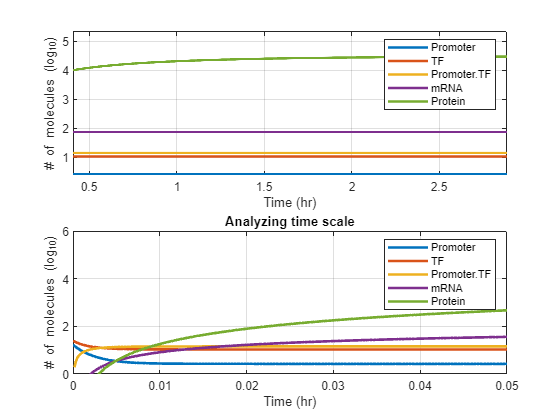

figure2 = figure('Color',[1 1 1]); 
subplot(211)
plot(time,log10(x0),'LineWidth',2);
 
ylabel({'# of molecules (log_{10})'});
xlabel('Time (hr)')
legend('Promoter','TF','Promoter.TF','mRNA','Protein')
axis([0 3 0 6])
grid on  

subplot(212)
plot(time,log10(x0),'LineWidth',2);
title('Analyzing time scale')
ylabel({'# of molecules (log_{10})'});
xlabel('Time (hr)')
legend('Promoter','TF','Promoter.TF','mRNA','Protein')
axis([0 0.05 0 6])
grid on  

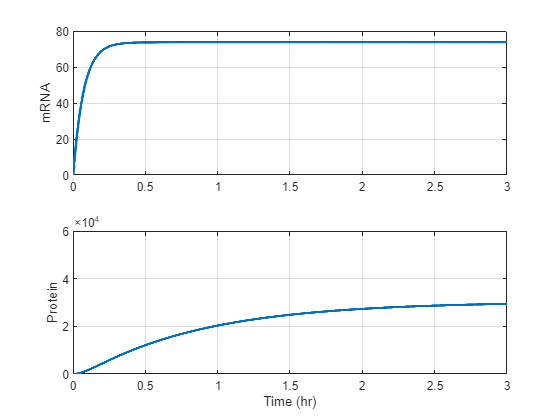

%Plots
 figure1 = figure('Color',[1 1 1]); 
 subplot(211)
 plot(time,(x0(:,4)),'LineWidth',2);
 ylabel('mRNA')
 axis([0 3 0 80])
grid on
 hold on
subplot(212) 
 plot(time,(x0(:,5)),'LineWidth',2);
 xlabel('Time (hr)')
ylabel('Protein')
 axis([0 3 0 6e4])
grid on

function [dxdt] = model_TF(t,x,p)
Prom = x(1);
TF = x(2);
Complex = x(3);
mRNA = x(4);
Prot = x(5);

%x1 = Promoter
dxdt(1,1) = -p.kon .* Prom .* TF +p.koff .* Complex;
%x2 = TF
dxdt(2,1) = -p.kon .* Prom .* TF +p.koff .* Complex;
%x3 = Promoter.TF
dxdt(3,1) = +p.kon .* Prom .* TF -p.koff .* Complex;
%x4 = mRNA
dxdt(4,1) = Complex .* p.k1- p.d1*mRNA;
%x5 = Protein
dxdt(5,1)= p.k2 .* mRNA -p.d2 .* Prot;
end